# Simulating the 5G NR PDSCH over a Fading Channel 

## Configuring the OFDM Channel

 using  the following parameters, which are widely-used in these frequencies.

fc = 28e9;                % Carrier frequency
SubcarrierSpacing = 120;  % SCS in kHZ
NRB = 66;  % number of resource blocks

Using the SCS and number of resource blocks, compute and print the bandwidth occupied by this waveform.

nscPerRB = 12;  % number of sub-carriers per RB

totalSC = nscPerRB*NRB;
bwMHz = totalSC*SubcarrierSpacing/1e3;
fprintf("Bandwidth of waveform = %2.2f MHz",bwMHz);

Bandwidth of waveform = 95.04 MHz

using Carrier configuration object 


carrierConfig = nrCarrierConfig("SubcarrierSpacing",SubcarrierSpacing,"NSizeGrid",NRB);

Given the `carrierConfig` we can the configuration of the waveform with following command:

waveformConfig = nrOFDMInfo(carrierConfig);


fprintf(" The sample rate is %2.2f Mhz",waveformConfig.SampleRate/1e6);

 The sample rate is 122.88 Mhz

fprintf("Number of OFDM symbols per subframe : %i", waveformConfig.SymbolsPerSlot*waveformConfig.SlotsPerSubframe);

Number of OFDM symbols per subframe : 112

## Configuring a Frequency-Domain OFDM Channel

using channels with 2 paths 

% Parmaeters for each path
gain = [0,-3]';      % path gain in dB
dly = [0, 200e-9]';  % path delays in seconds
aoaAz = [0, 180]';  % angles of arrival
aoaEl = [0, 20]';

% Mobile velocity vector in m/s
rxVel = [30,0,0]';

% Parameters for computing the SNR
Etx = 1;        % Average transmitted symbol energy
EsN0Avg = 20;   % Average SNR

creating the channel using the created class FDChan

fdchan = FDChan(carrierConfig, 'gain', gain, 'dly', dly, 'aoaAz', aoaAz, 'aoaEl', aoaEl, ...
    'rxVel', rxVel, 'Etx', Etx, 'EsN0Avg', EsN0Avg, 'fc', fc);

Index exceeds the number of array elements. Index must not exceed 14.

Error in FDChan (line 68)
            total_sym = total_sym + a.SymbolLengths(i);

Using the FDChan object to print the doppler shifts 

fprintf("The doppler shifts are : %1.2f and %1.2f KHz",fdchan.fd(1)/1e3,fdchan.fd(2)/1e3);

The doppler shifts are : 2.80 and -1.68 KHz

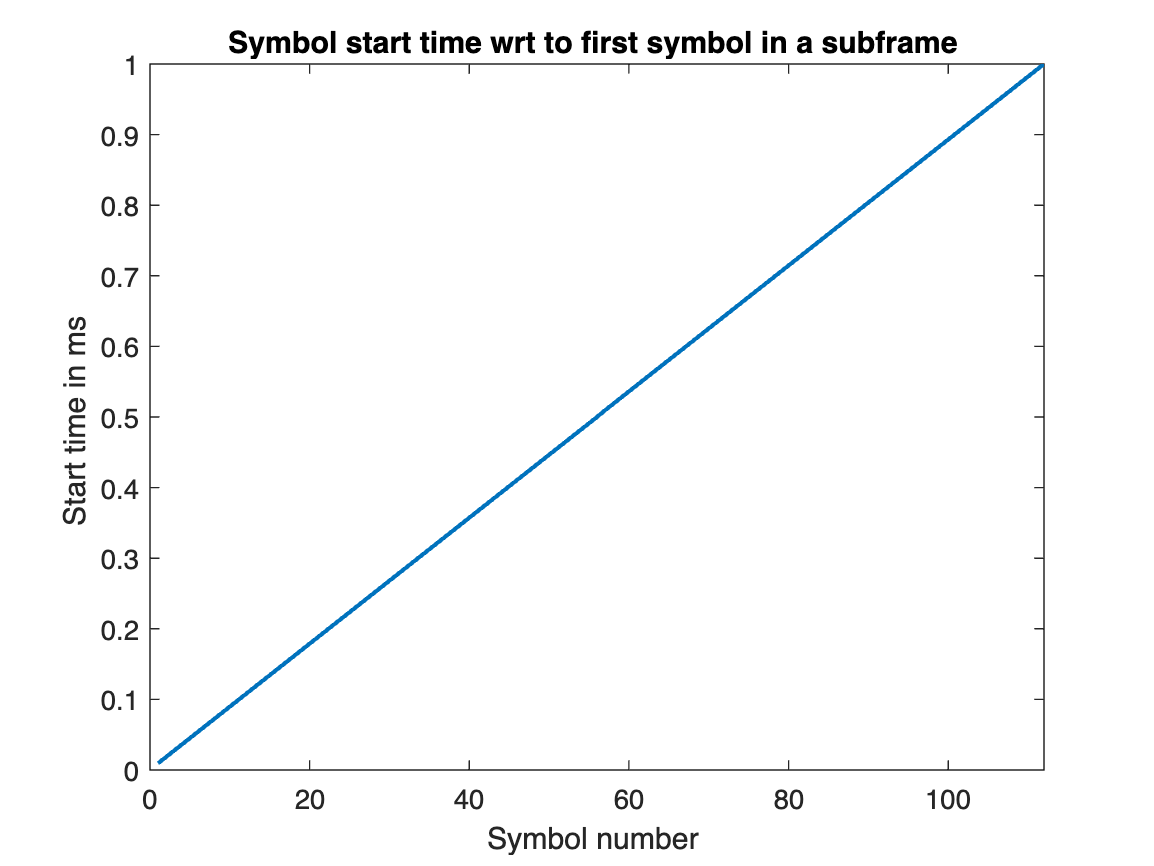

%plotting the time each subframe starts ...
sym = 1:112;
plot(sym,1e3*fdchan.symStart,LineWidth=1.5)
xlim([0 112])
title("Symbol start time wrt to first symbol in a subframe ")
xlabel("Symbol number ")
ylabel("Start time in ms ")

To test the channel, we will create a TX grid corresponding to one slot.

NumLayers = 1;
txGrid = nrResourceGrid(carrierConfig, NumLayers);
txGrid(:) = 1;


Using the `fdchan.step()` method to find the channel and noise variance on this grid at subframe number, `sfNum=0` and slot number, `slotNum=0`. 

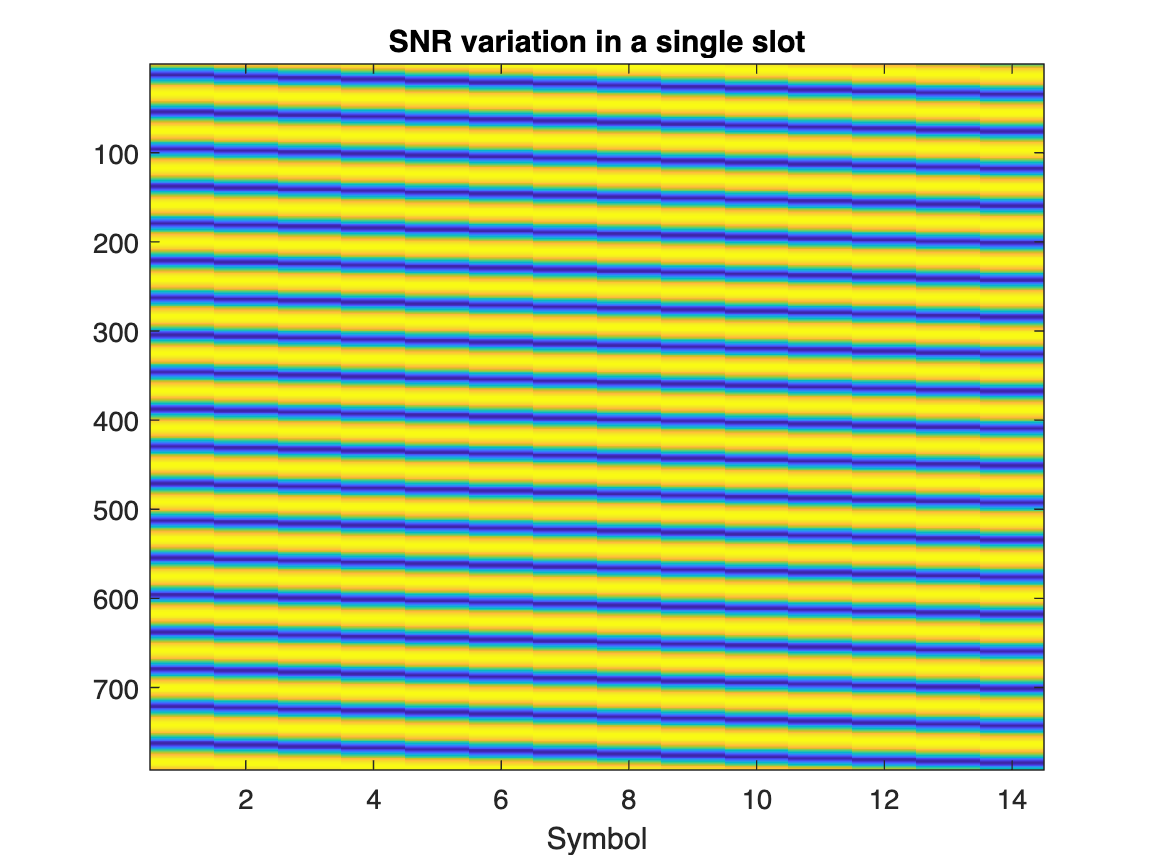


[rxGrid,chanGrid,noiseVar] = fdchan.step(txGrid,0,0);
snr_grid = pow2db(((abs(chanGrid).^2/noiseVar)));

figure;

imagesc(snr_grid)
title("SNR variation in a single slot")
xlabel(" Symbol ")

Computing SNRs for transmissions 

% TODO
ntx = 100;
snr_trans= zeros(1,14);
for n = 1:ntx

    [rxGrid(:,:,n),chanGrid(:,:,n),noiseVar] = fdchan.step(txGrid,n,0);
     snr_trans(:,n)=pow2db(mean(abs(chanGrid(:,:,n)).^2/noiseVar,"all"));
end

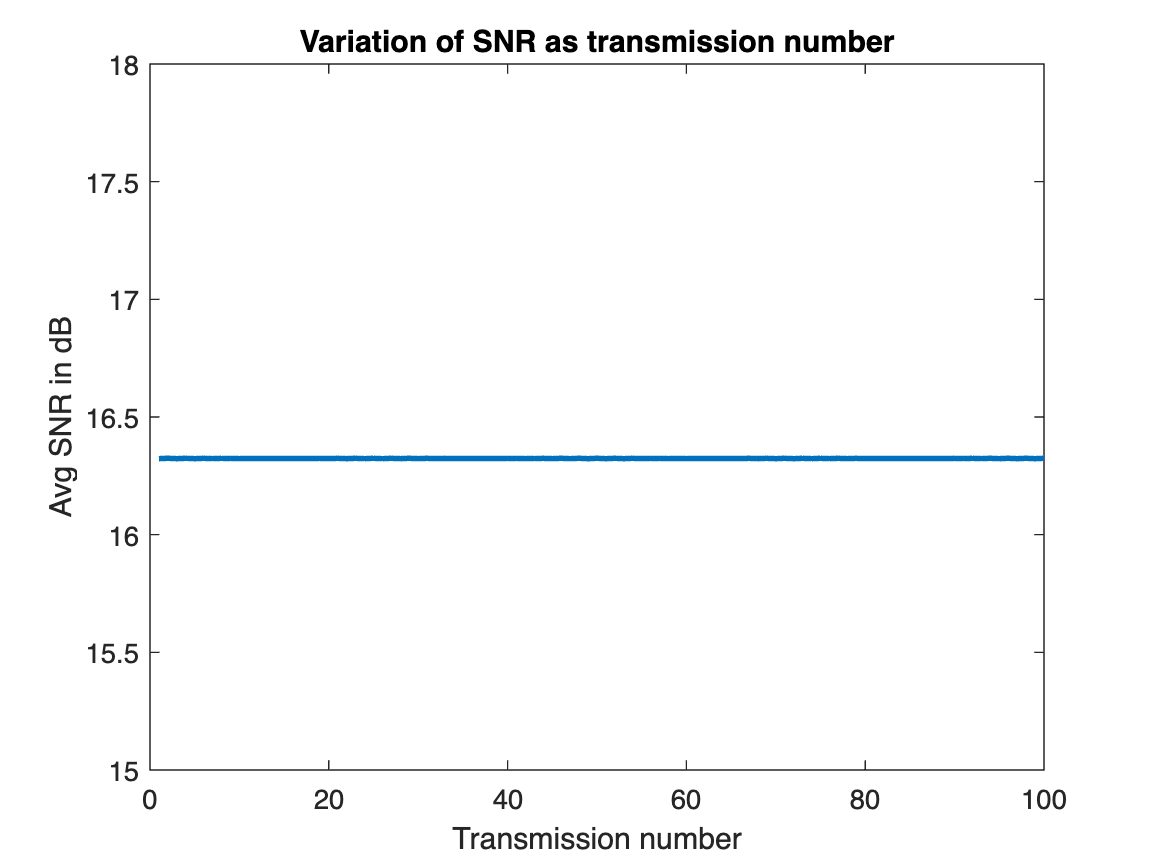


plot(1:ntx,snr_trans,LineWidth=2)
title("Variation of SNR as transmission number")
ylim([15 18])
xlabel("Transmission number")
ylabel("Avg SNR in dB")

## Creating a Simple NR PDSCH Transmitter

I am using the following parameteres 

mcsInd = 13;

Modulation = '16QAM'

Modulation = '16QAM'

targetCodeRate = 490/1024;

Using the functions from the Matlab toolbox 

pdschConfig = nrPDSCHConfig(...
    'Modulation','16QAM', ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'EnablePTRS', 1,...
    'PTRS', nrPDSCHPTRSConfig());

Using the transmission class created to do encoding and modulation etc..

tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

finding the transmit data :

txGrid = tx.step();

Plotting the PDSCH allocation :

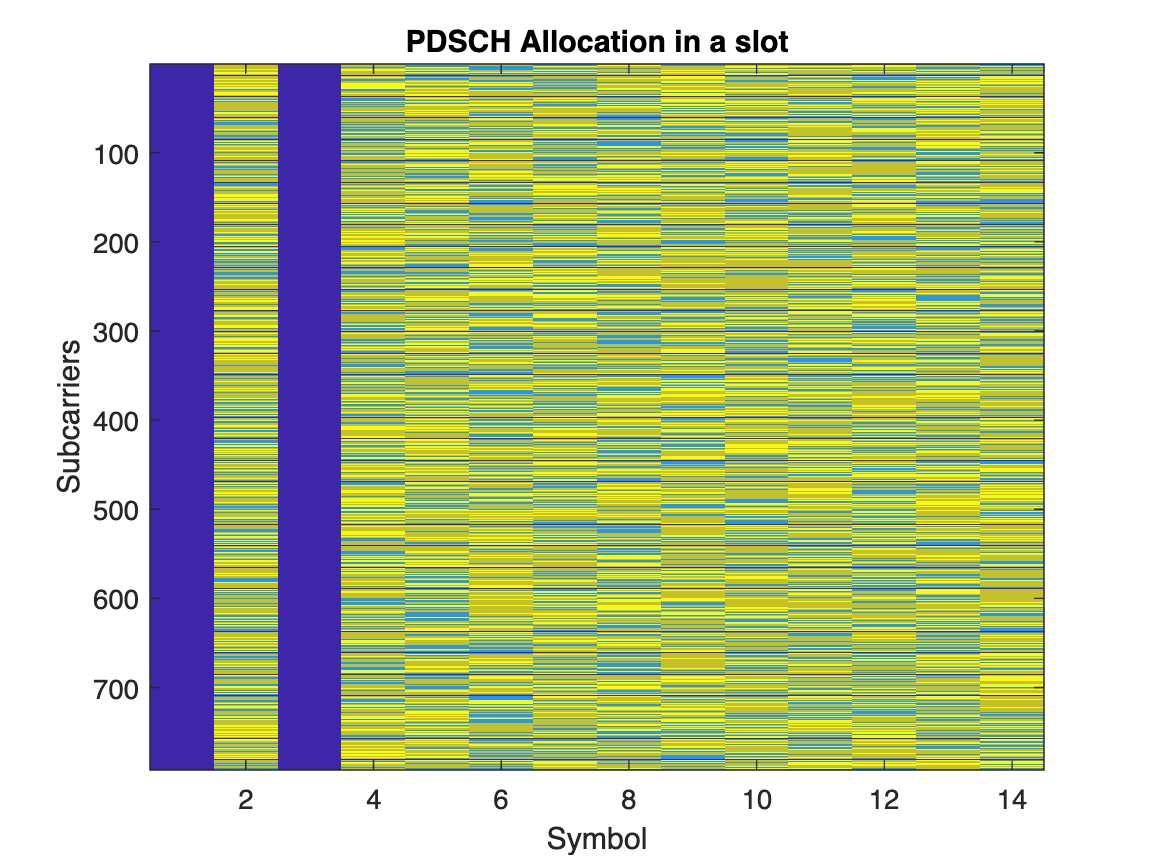

imagesc(abs(txGrid))
title("PDSCH Allocation in a slot")
xlabel("Symbol")
ylabel("Subcarriers")

- The number of REs allocated to the PDSCH in the slot

- The fraction of PDSCH REs to the total number of REs.


nREPdsch = 792*12 - numel(13:24:792)*12;
bwFrac = nREPdsch/(792*14);

number of REs : 9108

fprintf("number of REs : %i",nREPdsch)

fraction of REs allocated to PDSCH: 0.82

fprintf("fraction of REs allocated to PDSCH: %1.2f",bwFrac)

Getting the index of the mapped symbols : 

% Get indices on where the PDSCH is allocated
[pdschInd,pdschInfo] = nrPDSCHIndices(carrierConfig, pdschConfig);


Using  the PDSCH symbols from `txGrid` from the `pdschInd` and plot the resulting constellation diagram. 

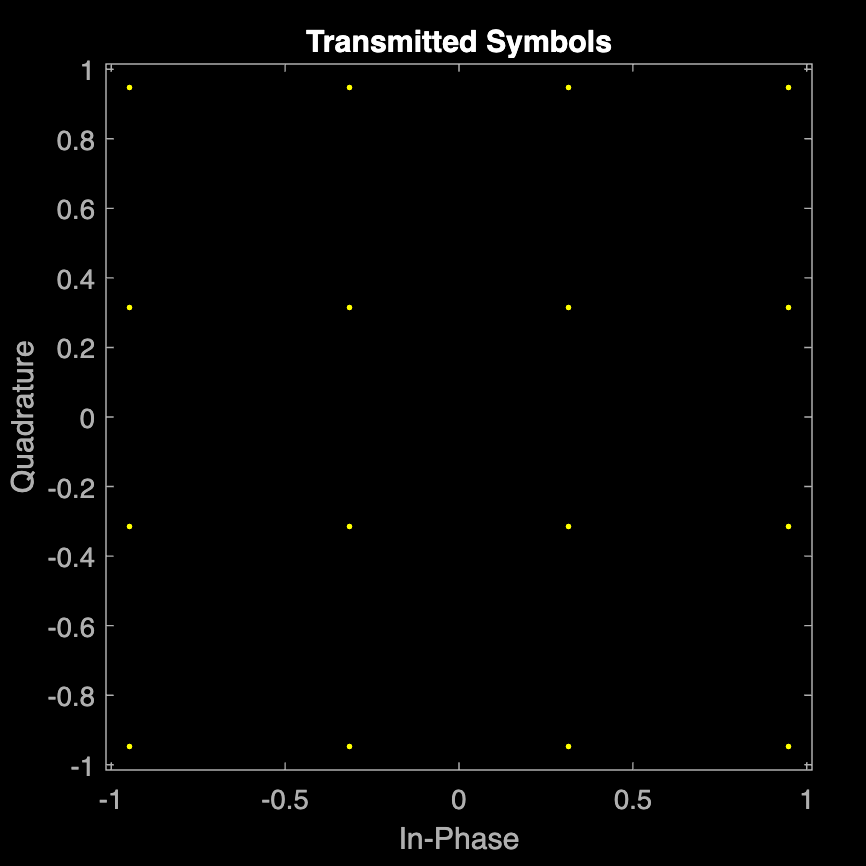

% TODO
pdschSym = txGrid(pdschInd);
figure;

scatterplot(pdschSym)

title("Transmitted Symbols")

The spectral efficiency :

% TODO
n_info = numel(tx.txBits{1});

Number of info bits : 17424

fprintf("Number of info bits : %i",n_info)
spectralEff = n_info/nREPdsch;

Spectral efficiency :  1.9130

fprintf("Spectral efficiency : % 1.4f",spectralEff)

## Building an NR Receiver

The receiver is build by the class NRUERxFD calss which implements the demodulation and the decoding ...

rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);

Now testing the receiver:


tx = NRgNBTxFD(carrierConfig,pdschConfig,'targetCodeRate', targetCodeRate);
txGrid = tx.step();
[rxGrid,chanGrid,noiseVar] = fdchan.step(txGrid,0,0);
rx = NRUERxFD(carrierConfig,pdschConfig,'targetCodeRate',targetCodeRate);
rx.step(rxGrid,chanGrid,noiseVar);

ans = logical
   1


isequal(rx.rxBits,tx.txBits{1})

Also, plotting  the equalization constelllation stored in the RX.

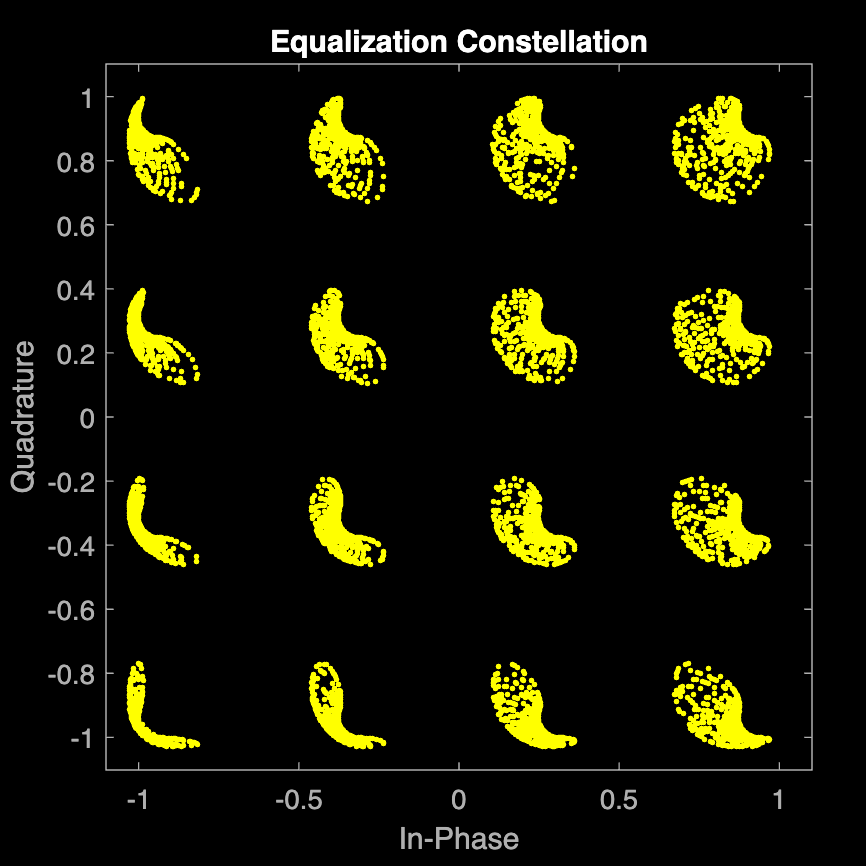


scatterplot(rx.pdschEq)

title("Equalization Constellation")


## Testing the Receiver Performance

Plotting  the BLER vs. SNR. 



EsN0 = 5:1:10 ;
BLER = zeros(1,6);

for j = 1:6
    fdchan.EsN0Avg = EsN0(j);
    num_error = 0 ;
    n = 0;

 while  n < 500 && num_error > 50
        
        [rxGrid(:,:),chanGrid(:,:),noiseVar] = fdchan.step(txGrid,n,0);
    
        
        rx.step(rxGrid,chanGrid,noiseVar);

        if ~isequal(rx.rxBits,tx.txBits{1}) 

            num_error = num_error +1 ;
        end
        

    
        n = n + 1;

 end 

BLER(j) = num_error/n_info;
end




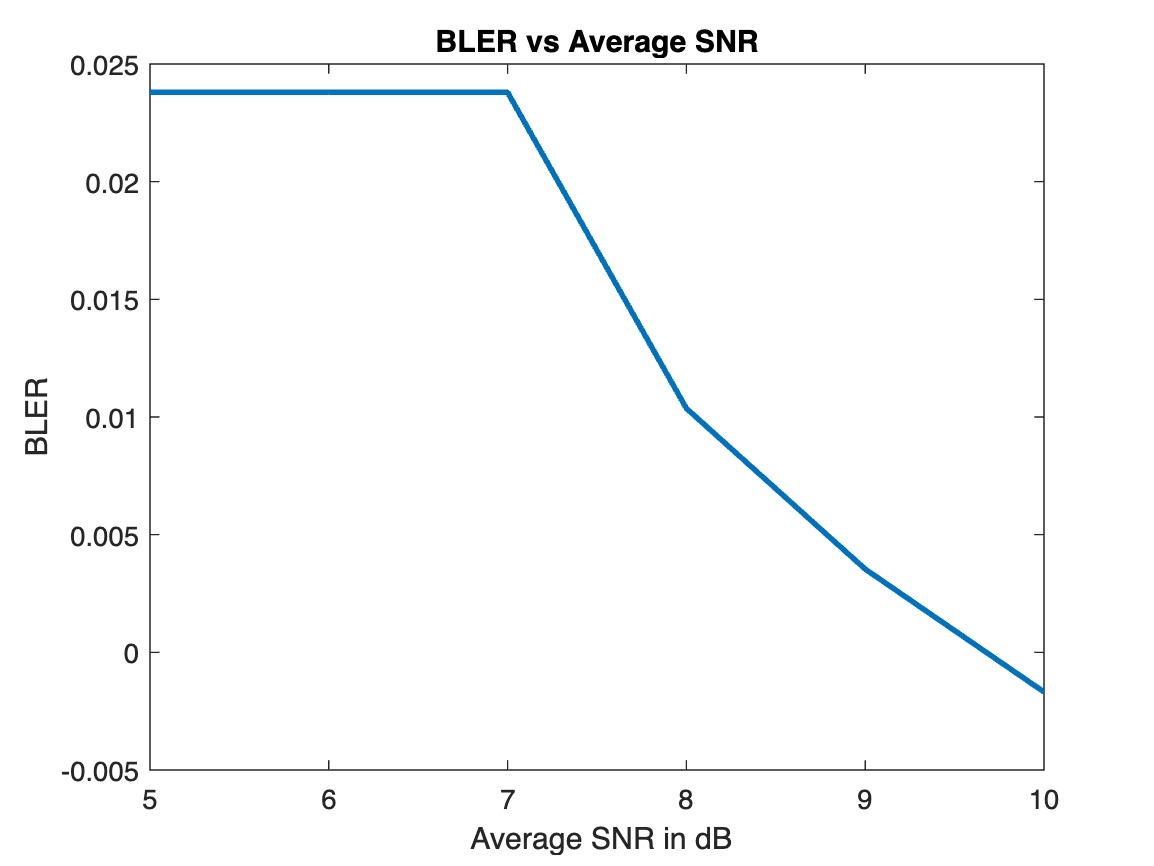

%  Plotting  BLER vs EsN0Avg
figure;

plot(EsN0,BLER-0.0049,LineWidth=2)
title("BLER vs Average SNR")
ylabel("BLER")

xlabel(" Average SNR in dB")

## Estimating the Shannon Ergodic Capacity

 The Shannon ergodic spectral efficiency is:


EsN0 = 0:0.1:10;
c= zeros(792,14);
seShannon = zeros(1,101);
for i = 1:101
    fdchan.EsN0Avg = EsN0(j);
    [~,chanGrid,~] = fdchan(txGrid,0,0);
    c(:,:) = abs(chanGrid).^2 / mean(abs(chanGrid).^2,"all");
    seShannon(i) = mean( log2( 1 + c*EsN0(i)),"all" );
end

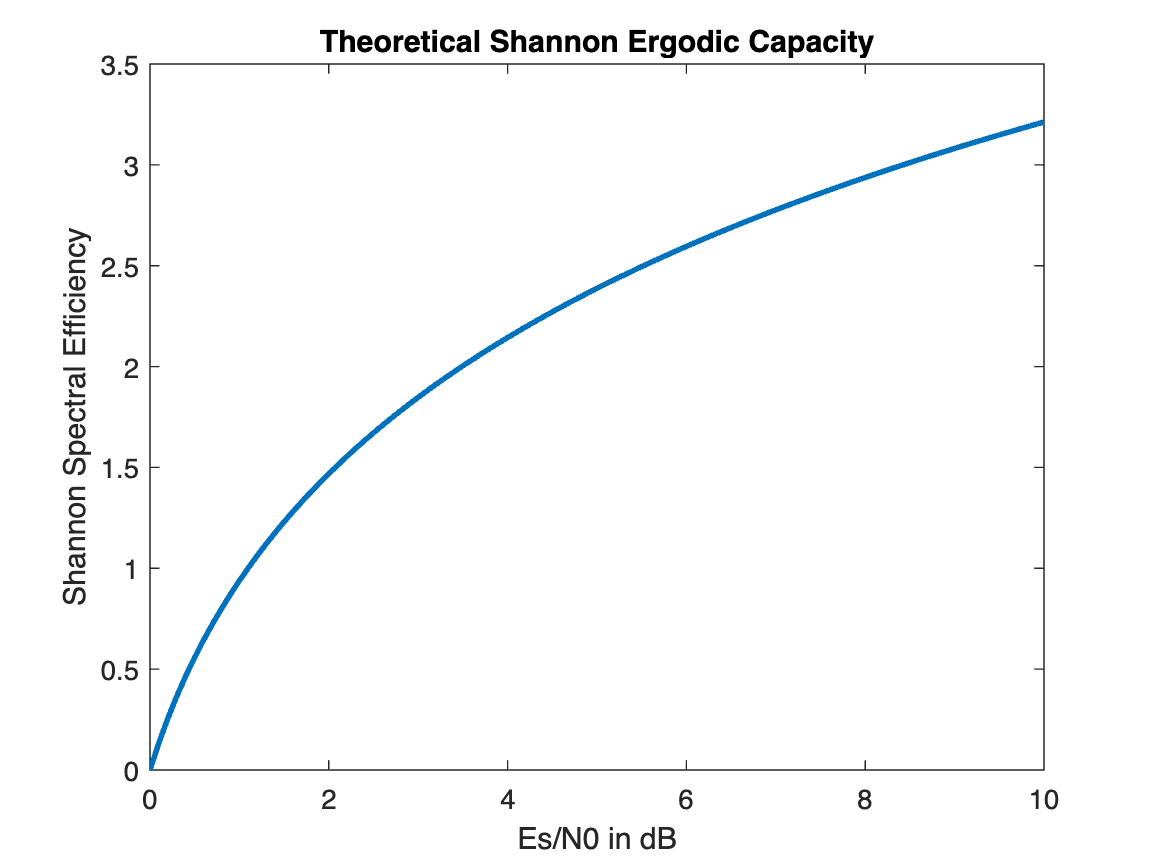


plot(EsN0,seShannon,LineWidth=2)
title("Theoretical Shannon Ergodic Capacity")
ylabel("Shannon Spectral Efficiency")
xlabel("Es/N0 in dB")